inner_radius = 0.5;
outer_radius = 10.0;
n = 32;
% x and x are of (theta, r) direction
[x, y, r, dtheta] = gen_donut_mesh2(inner_radius, outer_radius, n);
z = readtable('stable_data.csv');

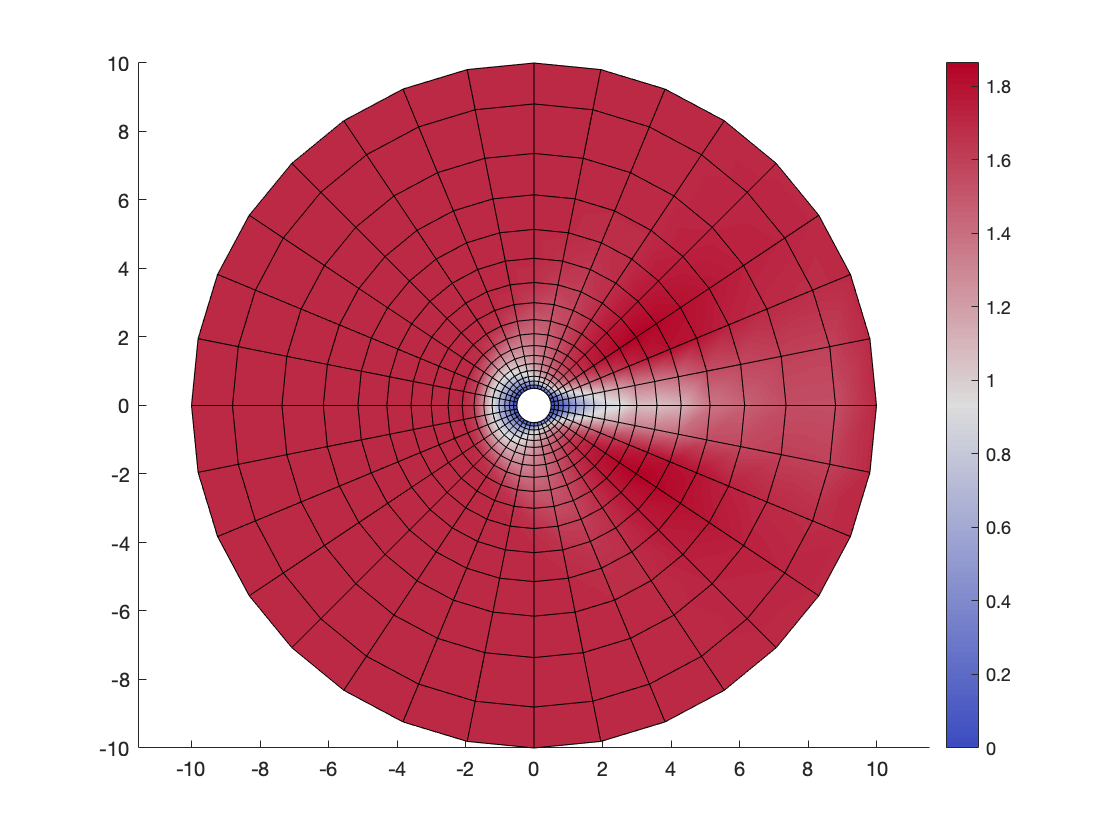

z = z{:,:};
z = reshape(z, [32, 18, 4]);
z = z(:,:,1);
z = [z;z(1,:)];
plot_2d(inner_radius, outer_radius, n, z);

### Bilinear prolongation

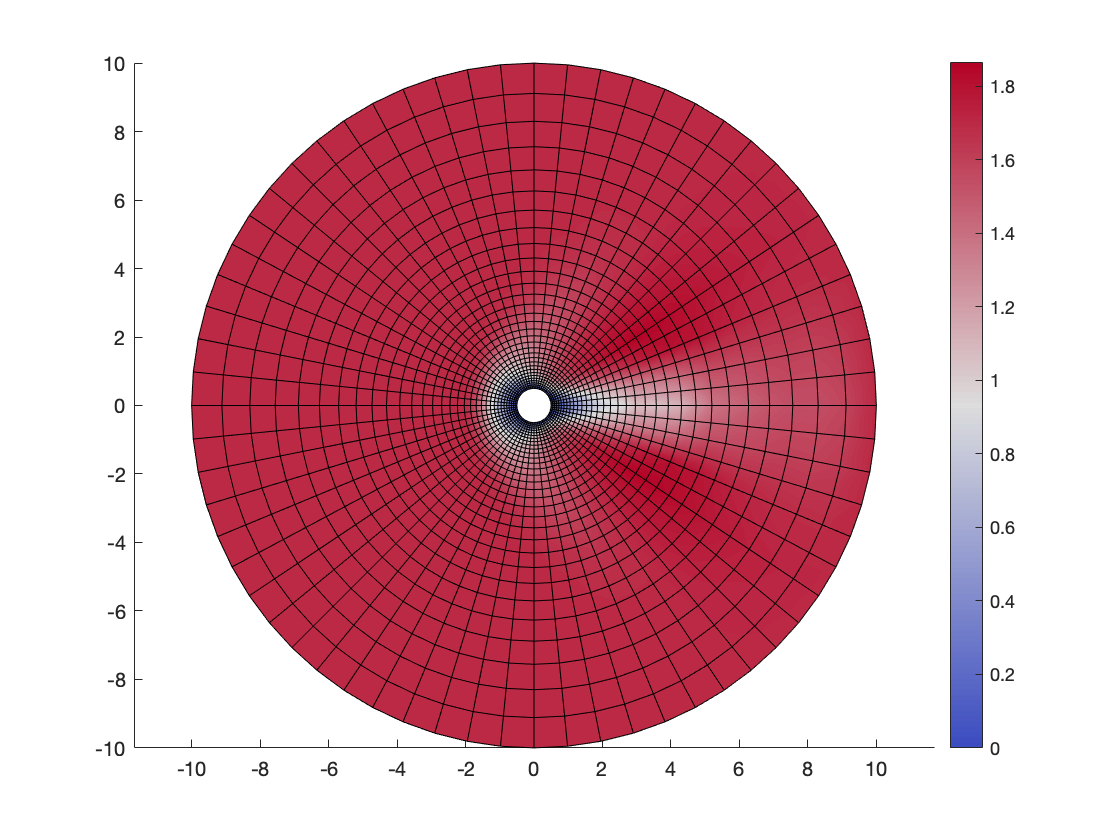

mesh_size = size(z);
theta_size = mesh_size(1) - 1;
r_size = mesh_size(2);

N = 64;
[X, ~, R, dTheta] = gen_donut_mesh2(inner_radius, outer_radius, N);
Z1 = zeros(size(X));
for i = 1:theta_size+1
    Z1(2*i-1,1) = z(i,1);
    Z1(2*i-1,end) = z(i,end);
end
for i = 1:theta_size
    R_index = 1;
    for j = 1:r_size-1
        while R(R_index) < r(j+1)
            xr = (R(R_index) - r(j)) / (r(j+1) - r(j));
            if R_index ~= 1 && R_index ~= length(R)
                Z1(2*i-1,R_index) = z(i,j) + xr * (z(i,j+1) - z(i,j));
            end
            R_index = R_index + 1;
        end
    end
end
Z1(end,:) = Z1(1,:);
for i = 1:theta_size
    for j = 1:length(R)
        Z1(2*i,j) = (Z1(2*i-1,j) + Z1(2*i+1,j)) / 2;
    end
end
plot_2d(inner_radius, outer_radius, N, Z1);

### Bicubic prolongation

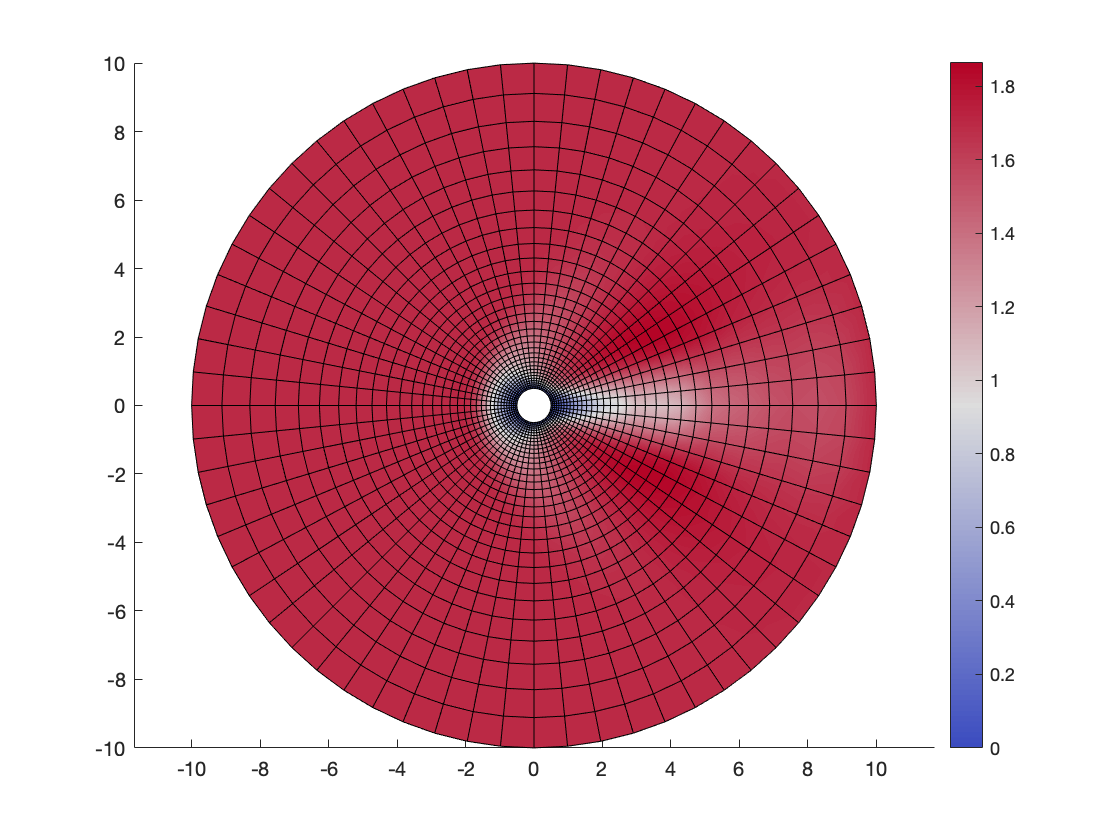

A = [1,0,0,0;0,0,1,0;-3,3,-2,-1;2,-2,1,1];
B = [1,0,-3,2;0,0,3,-2;0,1,-2,1;0,0,-1,1];
F = z;
mesh_size = size(z);
theta_size = mesh_size(1) - 1;
r_size = mesh_size(2);
deltar = r(2:end) - r(1:end-1);
deltat = r * dtheta;
Fr = zeros(mesh_size); Ft = zeros(mesh_size); Frt = zeros(mesh_size);
for i = 1:theta_size+1
    Fr(i,1) = (z(i,2) - z(i,1)) / deltar(1);
    for j = 2:r_size-1
        Fr(i,j) = (z(i,j+1) - z(i,j-1)) / (deltar(j-1) + deltar(j));
    end
    Fr(i,r_size) = (z(i,r_size) - z(i,r_size-1)) / deltar(r_size-1);
end
for j = 1:r_size
    Ft(1,j) = (z(2,j) - z(end-1,j)) / (2 * deltat(j));
    for i = 2:theta_size
        Ft(i,j) = (z(i+1,j) - z(i-1,j)) / (2 * deltat(j));
    end
    Ft(end,j) = Ft(1,j);
end
Frt(1,1) = (r(1) * (z(2,2) - z(end-1,2)) - r(2) * (z(2,1) - z(end-1,1))) / (2 * deltar(1) * r(2) * deltat(1));
for j = 2:r_size-1
    Frt(1,j) = (r(j-1) * (z(2,j+1) - z(end-1,j+1)) - r(j+1) * (z(2,j-1) - z(end-1,j-1))) / (2 * (deltar(j-1) + deltar(j)) * r(j+1) * deltat(j-1));
end
Frt(1,r_size) = (r(r_size-1) * (z(2,r_size) - z(end-1,r_size)) - r(r_size) * (z(2,r_size-1) - z(end-1,r_size-1))) / (2 * deltar(r_size-1) * r(r_size-1) * deltat(r_size));
for i = 2:theta_size
    Frt(i,1) = (r(1) * (z(i+1,2) - z(i-1,2)) - r(2) * (z(i+1,1) - z(i-1,1))) / (2 * deltar(1) * r(2) * deltat(1));
    for j = 2:r_size-1
        Frt(i,j) = (r(j-1) * (z(i+1,j+1) - z(i-1,j+1)) - r(j+1) * (z(i+1,j-1) - z(i-1,j-1))) / (2 * (deltar(j-1) + deltar(j)) * r(j+1) * deltat(j-1));
    end
    Frt(i,r_size) = (r(r_size-1) * (z(i+1,r_size) - z(i-1,r_size)) - r(r_size) * (z(i+1,r_size-1) - z(i-1,r_size-1))) / (2 * deltar(r_size-1) * r(r_size-1) * deltat(r_size));
end
for j = 1:r_size
    Frt(theta_size+1,j) = Frt(1,j);
end

N = 64;
[X, Y, R, ~] = gen_donut_mesh2(inner_radius, outer_radius, N);
Z2 = zeros(size(X));
for i = 1:theta_size+1
    Z2(2*i-1,1) = z(i,1);
    Z2(2*i-1,end) = z(i,end);
end
resizer = 1 ./ deltar;
resizet = 1 ./ deltat;
for i = 1:theta_size
    R_index = 1;
    for j = 1:r_size-1
        f = F(i:i+1,j:j+1)';
        fr = Fr(i:i+1,j:j+1)' ./ resizer(j);
        ft = (Ft(i:i+1,j:j+1) ./ [resizet(j) resizet(j+1)])';
        frt = (Frt(i:i+1,j:j+1) ./ resizer(j) ./ [resizet(j) resizet(j+1)])';
        C = [f,ft;fr,frt];
        P = A*C*B;
        while R(R_index) < r(j+1)
            xr = (R(R_index) - r(j)) / deltar(j);
            if R_index ~= 1 && R_index ~= length(R)
                Z2(2*i-1,R_index) = [1,xr,xr^2,xr^3] * P * [1;0;0;0];
            end
            Z2(2*i,R_index) = [1,xr,xr^2,xr^3] * P * [1;0.5;0.5^2;0.5^3];
            R_index = R_index + 1;
        end
        if j == r_size-1
            Z2(2*i,R_index) = [1,1,1,1] * P * [1;0.5;0.5^2;0.5^3];
        end
    end
end
Z2(end,:) = Z2(1,:);
plot_2d(inner_radius, outer_radius, N, Z2);

### Bicubic restriction

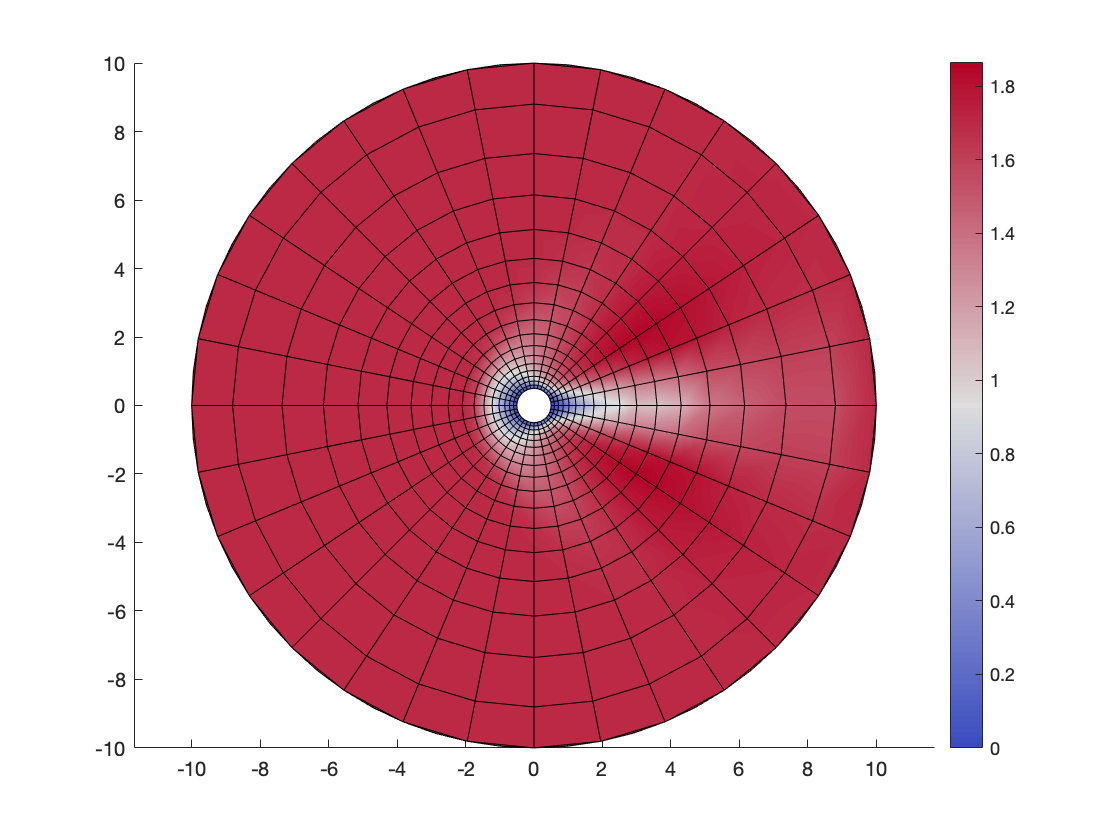

A = [1,0,0,0;0,0,1,0;-3,3,-2,-1;2,-2,1,1];
B = [1,0,-3,2;0,0,3,-2;0,1,-2,1;0,0,-1,1];
F = Z2;
mesh_size = size(Z2);
theta_size = mesh_size(1) - 1;
r_size = mesh_size(2);
deltar = R(2:end) - R(1:end-1);
deltat = R * dtheta;
Fr = zeros(mesh_size); Ft = zeros(mesh_size); Frt = zeros(mesh_size);
for i = 1:theta_size+1
    Fr(i,1) = (F(i,2) - F(i,1)) / deltar(1);
    for j = 2:r_size-1
        Fr(i,j) = (F(i,j+1) - F(i,j-1)) / (deltar(j-1) + deltar(j));
    end
    Fr(i,r_size) = (F(i,r_size) - F(i,r_size-1)) / deltar(r_size-1);
end
for j = 1:r_size
    Ft(1,j) = (F(2,j) - F(end-1,j)) / (2 * deltat(j));
    for i = 2:theta_size
        Ft(i,j) = (F(i+1,j) - F(i-1,j)) / (2 * deltat(j));
    end
    Ft(end,j) = Ft(1,j);
end
Frt(1,1) = (R(1) * (F(2,2) - F(end-1,2)) - R(2) * (F(2,1) - F(end-1,1))) / (2 * deltar(1) * R(2) * deltat(1));
for j = 2:r_size-1
    Frt(1,j) = (R(j-1) * (F(2,j+1) - F(end-1,j+1)) - R(j+1) * (F(2,j-1) - F(end-1,j-1))) / (2 * (deltar(j-1) + deltar(j)) * R(j+1) * deltat(j-1));
end
Frt(1,r_size) = (R(r_size-1) * (F(2,r_size) - F(end-1,r_size)) - R(r_size) * (F(2,r_size-1) - F(end-1,r_size-1))) / (2 * deltar(r_size-1) * R(r_size-1) * deltat(r_size));
for i = 2:theta_size
    Frt(i,1) = (R(1) * (F(i+1,2) - F(i-1,2)) - R(2) * (F(i+1,1) - F(i-1,1))) / (2 * deltar(1) * R(2) * deltat(1));
    for j = 2:r_size-1
        Frt(i,j) = (R(j-1) * (F(i+1,j+1) - F(i-1,j+1)) - R(j+1) * (F(i+1,j-1) - F(i-1,j-1))) / (2 * (deltar(j-1) + deltar(j)) * R(j+1) * deltat(j-1));
    end
    Frt(i,r_size) = (R(r_size-1) * (F(i+1,r_size) - F(i-1,r_size)) - R(r_size) * (F(i+1,r_size-1) - F(i-1,r_size-1))) / (2 * deltar(r_size-1) * R(r_size-1) * deltat(r_size));
end
for j = 1:r_size
    Frt(theta_size+1,j) = Frt(1,j);
end

N = 32;
[x, y, r, ~] = gen_donut_mesh2(inner_radius, outer_radius, N);
Z3 = zeros(size(x));
for i = 1:theta_size/2+1
    Z3(i,1) = Z2(2*i-1,1);
    Z3(i,end) = Z2(2*i-1,end);
end
resizer = 1 ./ deltar;
resizet = 1 ./ deltat;
for i = 1:theta_size/2
    r_index = 1;
    for j = 1:r_size-1
        if r(r_index) < R(j+1)
            f = F(2*i-1:2*i,j:j+1)';
            fr = Fr(2*i-1:2*i,j:j+1)' ./ resizer(j);
            ft = (Ft(2*i-1:2*i,j:j+1) ./ [resizet(j) resizet(j+1)])';
            frt = (Frt(2*i-1:2*i,j:j+1) ./ resizer(j) ./ [resizet(j) resizet(j+1)])';
            C = [f,ft;fr,frt];
            P = A*C*B;
            xr = (r(r_index) - R(j)) / deltar(j);
            if r_index ~= 1 && r_index ~= length(r)
                Z3(i,r_index) = [1,xr,xr^2,xr^3] * P * [1;0;0;0];
            end
            r_index = r_index + 1;
        end
    end
end
Z3(end,:) = Z3(1,:);
plot_2d(inner_radius, outer_radius, N, Z3);

disp(strcat("Average relative error = ", string(sum(sum(abs(z - Z3) ./ (z + 1e-16))) / 33 / 18)));

Average relative error = 0.00041522


### Bilinear Restriction

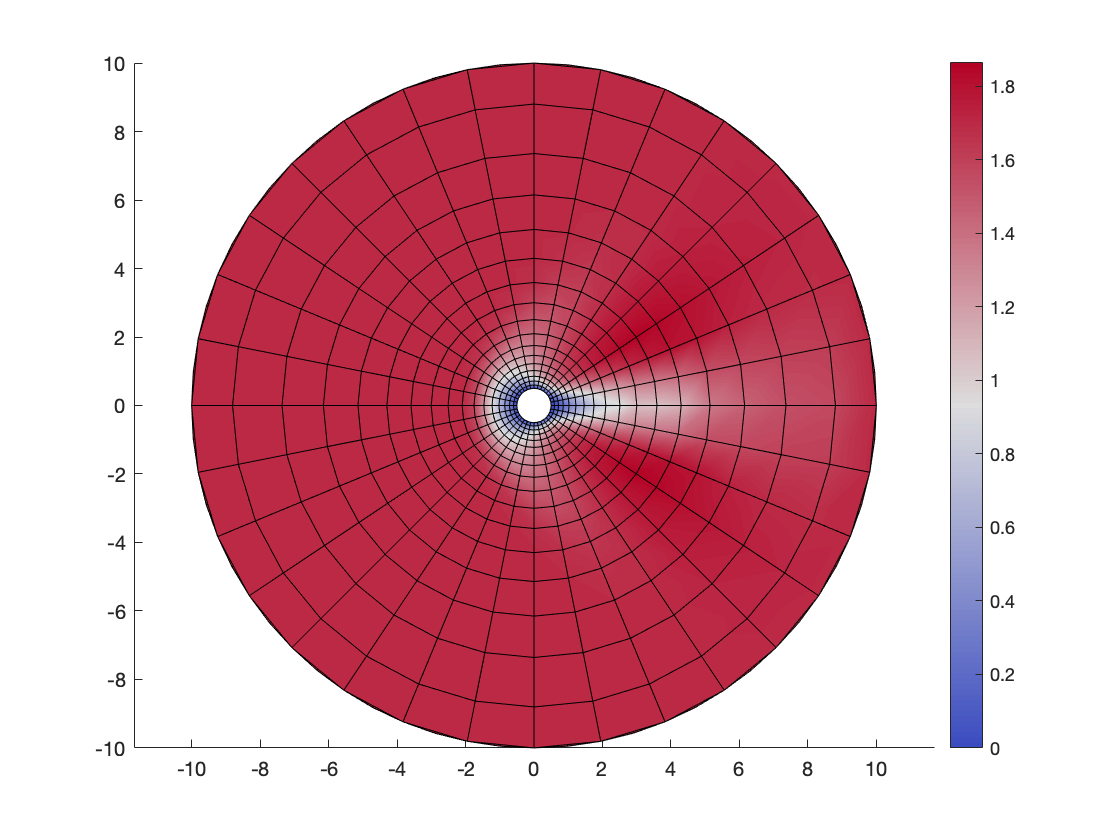

mesh_size = size(Z1);
theta_size = mesh_size(1) - 1;
r_size = mesh_size(2);

N = 32;
[x, ~, r, dtheta] = gen_donut_mesh2(inner_radius, outer_radius, N);
Z4 = zeros(size(x));
for i = 1:theta_size/2+1
    Z4(i,1) = Z1(2*i-1,1);
    Z4(i,end) = Z1(2*i-1,end);
end
for i = 1:theta_size/2
    r_index = 1;
    for j = 1:r_size-1
        while r(r_index) < R(j+1)
            xr = (r(r_index) - R(j)) / (R(j+1) - R(j));
            if r_index ~= 1 && r_index ~= length(r)
                Z4(i,r_index) = Z1(2*i-1,j) + xr * (Z1(2*i-1,j+1) - Z1(2*i-1,j));
            end
            r_index = r_index + 1;
        end
    end
end
Z4(end,:) = Z4(1,:);
plot_2d(inner_radius, outer_radius, N, Z4);

disp(strcat("Average relative error = ", string(sum(sum(abs(z - Z4) ./ (z + 1e-16))) / 33 / 18)));

Average relative error = 0.0040077
